# 中国人口比例变化趋势，以百分比表现

## 导入数据

clc; clear all; close all;
popu = xlsread(".//population.xlsx", "A8:D31");

## 各阶段人口数

data = popu(:, 2:4);

## 各阶段人口数百分比

a = size(data, 1);
for i=1:a
    age(i,1) = data(i, 1)/(sum(data(i,:)))*100;
    age(i,2) = data(i, 2)/(sum(data(i,:)))*100;
    age(i,3) = data(i, 3)/(sum(data(i,:)))*100;
end

## 各阶段人口增长速度变化趋势

for j=2:a
    age_incre(j-1,1) = (age(j,1)-age(j-1,1))/age(j-1,1) * 100 ;
    age_incre(j-1,2) = (age(j,2)-age(j-1,2))/age(j-1,2) * 100 ;
    age_incre(j-1,3) = (age(j,3)-age(j-1,3))/age(j-1,3) * 100 ;
end

## 数据可视化

date = datenum(num2str(popu(:,1)),"yyyymmdd");

### 人口数图

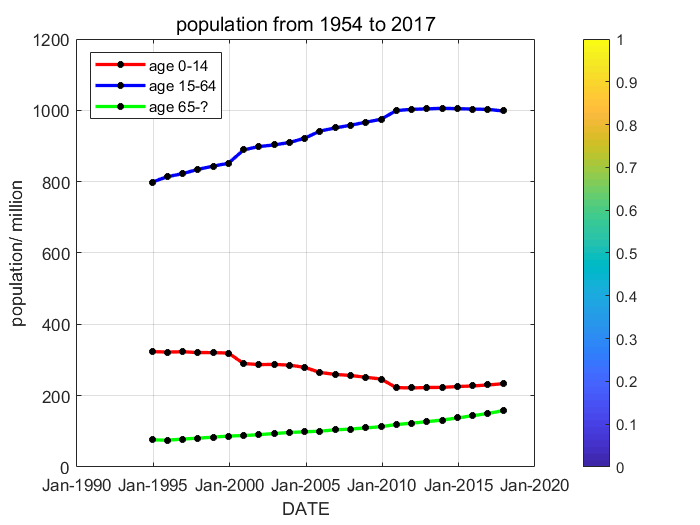

figure;
plot(date, data(:,1), "-r*",...
    "LineWidth",2,...
    "MarkerSize", 4,...
    "MarkerEdgeColor", "k")
%legend("age 0-14")
hold on
plot(date, data(:,2), "-b*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
%legend("age 15-64")
hold on
plot(date, data(:,3), "-g*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
legend("age 0-14","age 15-64","age 65-?","Location", 'northwest')

datetick("x", "mmm-yyyy")
xlabel("DATE")
ylabel("population/ million")
title("population from 1954 to 2017", "fontsize", 12)
colorbar
grid on

### 人口百分比图

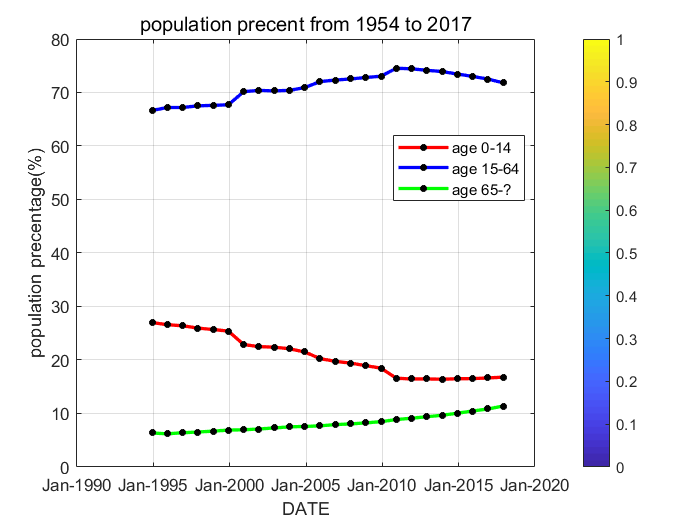

figure;
plot(date, age(:,1), "-r*",...
    "LineWidth",2,...
    "MarkerSize", 4,...
    "MarkerEdgeColor", "k")
%legend("age 0-14")
hold on
plot(date, age(:,2), "-b*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
%legend("age 15-64")
hold on
plot(date, age(:,3), "-g*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
legend("age 0-14","age 15-64","age 65-?","Location", 'best')

datetick("x", "mmm-yyyy")
xlabel("DATE")
ylabel("population precentage(%)")
title("population precent from 1954 to 2017", "fontsize", 12)
colorbar
grid on

### 人口增速百分比

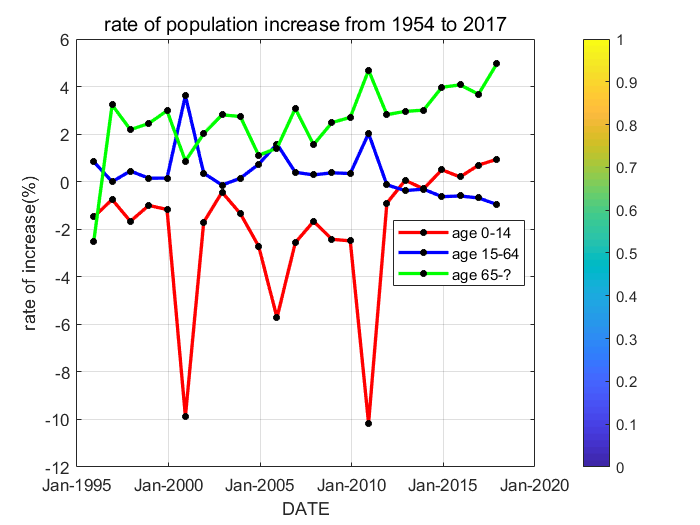

figure;
plot(date(2:24), age_incre(:,1), "-r*",...
    "LineWidth",2,...
    "MarkerSize", 4,...
    "MarkerEdgeColor", "k")
%legend("age 0-14")
hold on
plot(date(2:24), age_incre(:,2), "-b*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
%legend("age 15-64")
hold on
plot(date(2:24), age_incre(:,3), "-g*",...
    "LineWidth",2,...
    "MarkerSize",4,...
    "MarkerEdgeColor", "k")
legend("age 0-14","age 15-64","age 65-?","Location", 'best')

datetick("x", "mmm-yyyy")
xlabel("DATE")
ylabel("rate of increase(%)")
title("rate of population increase from 1954 to 2017", "fontsize", 12)
colorbar
grid on